## Parámetros

rotacion = 0; %pi/4
factor = 4/3; %1 a 4/3
lmin = 15;
es = 3.5;
hojas = 4;
n = 500;
v = 10; %[cm/s]

lcx = 22;
lcy = 9;

q10 = 180*(pi/180);
q20 = -165*(pi/180);

%Valores iniciales de los angulos
q10i = q10;
q20i = q20;

Ttotal = (4*lmin*factor)/v;
tTrebol = linspace(0,Ttotal,n);

l1 = 19;
l2 = 18;

## Trébol estilizado

[r,theta]=trayectoria0(rotacion,lmin, factor,es,hojas,n);

ans = 2.8870

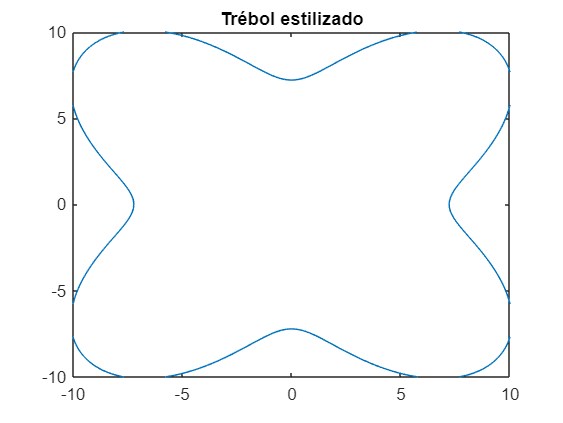


xp = r.*cos(theta);
yp = r.*sin(theta);
plot(xp,yp)
title('Trébol estilizado')
a = ((lmin/2)*factor)*(1+sin(rotacion));
xlim ([-a a])
ylim ([-a a])

## Trasladando al origen

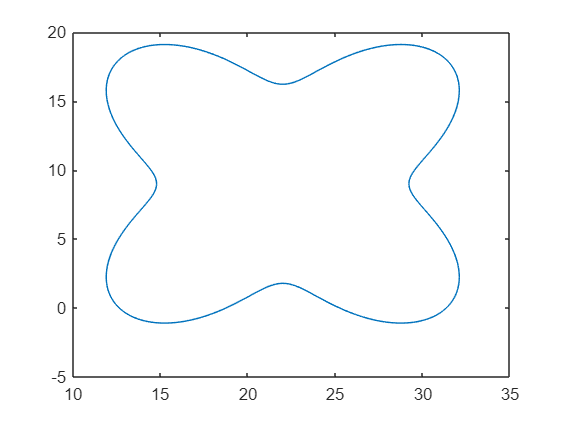

[x,y]=Totrigen(lcx,lcy,theta,r);
plot(x,y)

## Cinemática inversa

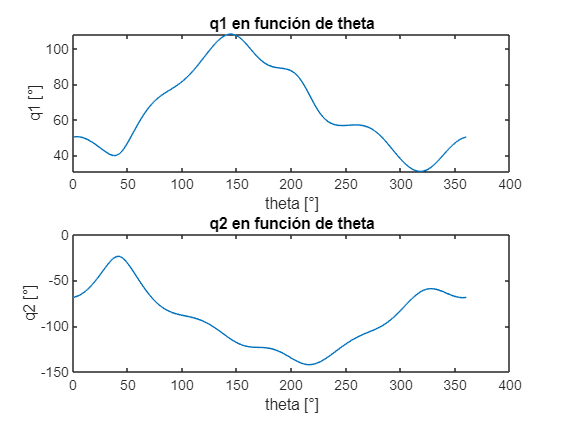

q1 = zeros(length(x),1);
q2 = zeros(length(x),1);
for i = 1:length(x)
    [q1(i), q2(i)] = Cinversa(l1,l2,x(i),y(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
end

figure()
subplot(2,1,1);
plot((theta)*(180/pi),q1*(180/pi))
title('q1 en función de theta')
ylabel('q1 [°]')
xlabel('theta [°]')

subplot(2,1,2); 
plot(theta*(180/pi),q2*(180/pi))
title('q2 en función de theta')
ylabel('q2 [°]')
xlabel('theta [°]')

## Trayectoria de acercamiento

[x20, y20] = Cdirecta(l1,l2,q10i,q20i); %Posición inicial extremo distal
[distPoint] = sqrt((x-x20).^2+(y-y20).^2);
minimo = min(distPoint)

minimo = 13.6730

pos = find(distPoint==minimo,1)

pos = 294

distPoint(pos);
%pos = (n/2) + 1; %Aprox en pi
[x2f, y2f] = Totrigen(lcx,lcy,theta(pos),r(pos));
Xaprox = linspace(x20,x2f,100);
Yaprox = linspace(y20,y2f,100);
% figure()
% hold on
% plot(Xaprox,Yaprox)
% plot(x,y)
% hold off

## Perfil trapezoidal Acercamiento

deltaX = x2f-x20

deltaX = 13.5547

deltaY = y2f-y20

deltaY = -1.7944

tAprox = 5; %s
t1 = tAprox/3; %Perfiles con tiempos iguales
VcX = (0.5*deltaX)/t1;
VcY = (0.5*deltaY)/t1;

t = linspace(0,tAprox,100);

mX = VcX/t1;
mY = VcY/t1;
Vx = mX*t-mX*(t-t1).*(t>=t1)-mX*(t-2*t1).*(t>=2*t1)

Vx =          0    0.1232    0.2464    0.3697    0.4929    0.6161    0.7393    0.8626    0.9858    1.1090    1.2322    1.3555    1.4787    1.6019    1.7251    1.8484    1.9716    2.0948    2.2180    2.3413    2.4645    2.5877    2.7109    2.8342    2.9574    3.0806    3.2038    3.3271    3.4503    3.5735    3.6967    3.8200    3.9432    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664    4.0664


Vy = mY*t-mY*(t-t1).*(t>=t1)-mY*(t-2*t1).*(t>=2*t1)

Vy =          0   -0.0163   -0.0326   -0.0489   -0.0653   -0.0816   -0.0979   -0.1142   -0.1305   -0.1468   -0.1631   -0.1794   -0.1958   -0.2121   -0.2284   -0.2447   -0.2610   -0.2773   -0.2936   -0.3099   -0.3263   -0.3426   -0.3589   -0.3752   -0.3915   -0.4078   -0.4241   -0.4404   -0.4568   -0.4731   -0.4894   -0.5057   -0.5220   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383   -0.5383


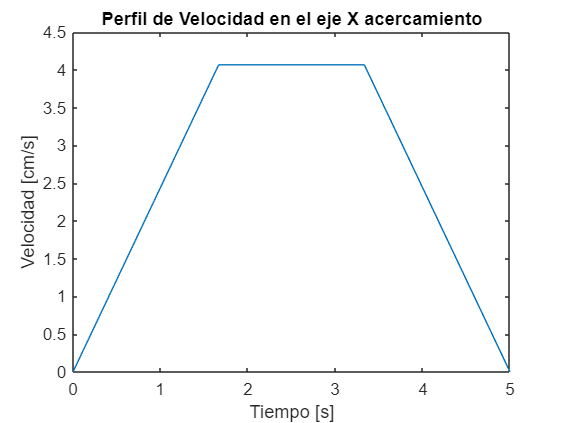


Px = 0.5*mX*t.^2-0.5*mX*((t-t1).^2).*(t>=t1)-0.5*mX*((t-2*t1).^2).*(t>=2*t1)+x20;

Py = 0.5*mY*t.^2-0.5*mY*((t-t1).^2).*(t>=t1)-0.5*mY*((t-2*t1).^2).*(t>=2*t1)+y20;

figure()
plot(t,Vx)
xlabel('Tiempo [s]')
ylabel('Velocidad [cm/s]')
title('Perfil de Velocidad en el eje X acercamiento')

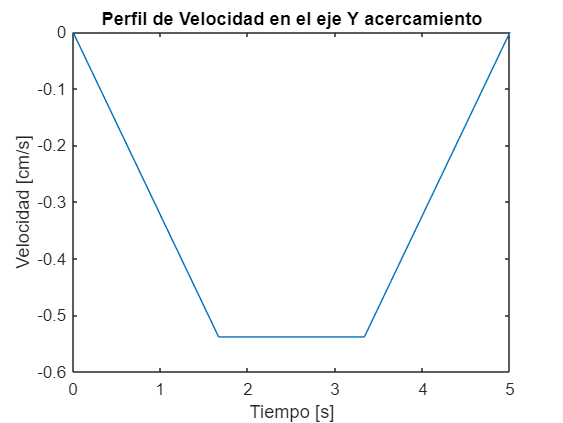


figure()
plot(t,Vy)
xlabel('Tiempo [s]')
ylabel('Velocidad [cm/s]')
title('Perfil de Velocidad en el eje Y acercamiento')

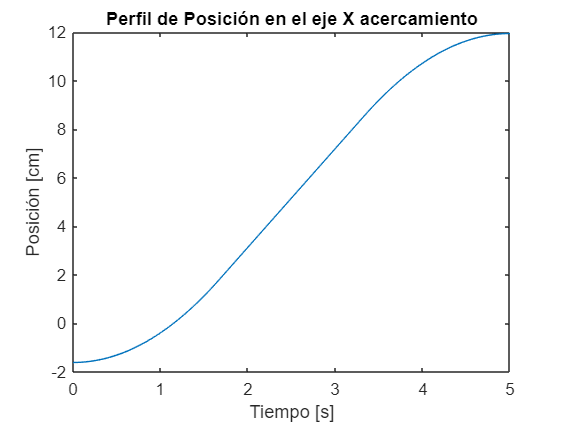


figure()
plot(t,Px)
xlabel('Tiempo [s]')
ylabel('Posición [cm]')
title('Perfil de Posición en el eje X acercamiento')

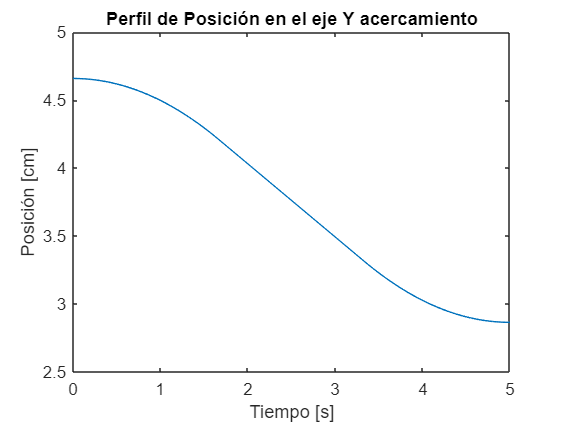


figure()
plot(t,Py)
xlabel('Tiempo [s]')
ylabel('Posición [cm]')
title('Perfil de Posición en el eje Y acercamiento')

## Visualización

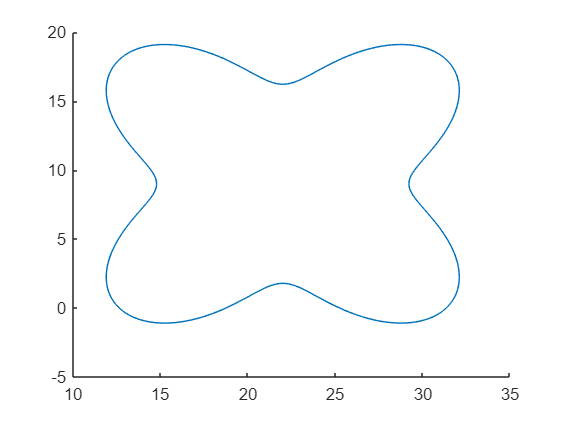

%Vectores de la posición distal del mecanismo en todo momento
XTotal = [Px, x(1,pos:end), x(1,1:pos-1)];
YTotal = [Py, y(1,pos:end), y(1,1:pos-1)];

%Cinematica inversa de todo el movimiento
q1 = zeros(1,length(XTotal));
q2 = zeros(1,length(YTotal));
figure(); %creamos la figura para visualizar
for i = 1:length(q1)
    %Cinematica inversa
    [q1(i), q2(i)] = Cinversa(l1,l2,XTotal(i),YTotal(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
    %Gráfica
    cla;    %clear axes
    hold on
    plot(x,y);%Trebol base
    %Primer eslabon
    x1 = l1*cos(q1(i));
    y1 = l1*sin(q1(i));
    %Segundo eslabon
    x2 = XTotal(i);
    y2 = YTotal(i);
%     plot([0 x1],[0 y1],'rd-','LineWidth',3)
%     plot([x1 x2],[y1 y2],'bd-','LineWidth',3)
%     pause(0.00001);
%     xlim([-40 40]);
%     ylim([-40 40]);
end


% figure()
% hold on
% x1 = l1*cos(q1(end));
%     y1 = l1*sin(q1(end));
%     %Segundo eslabon
%     x2 = XTotal(end);
%     y2 = YTotal(end);
%     plot([0 x1],[0 y1],'rd-','LineWidth',3)
%     plot([x1 x2],[y1 y2],'bd-','LineWidth',3)

## Vectores de posición angular

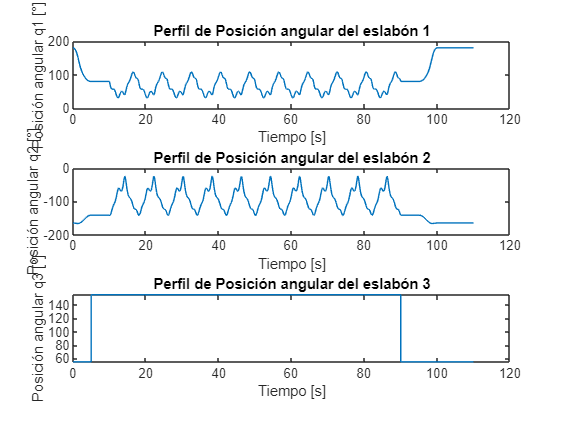

XAcercamiento = Px;
YAcercamiento = Py;

XTrebol = [x(1,pos:end), x(1,1:pos-1)];
YTrebol = [y(1,pos:end), y(1,1:pos-1)];

q3D = 155*(pi/180);
q3R = 55*(pi/180);

%Cinematica inversa del movimiento de acercamiento
q1Ace = zeros(1,length(XAcercamiento));
q2Ace = zeros(1,length(XAcercamiento));
q3Ace = q3R*ones(1,length(XAcercamiento));

q10 = 180*(pi/180);
q20 = -165*(pi/180);

for i = 1:length(q1Ace)
    %Cinematica inversa
    [q1Ace(i), q2Ace(i)] = Cinversa(l1,l2,XAcercamiento(i),YAcercamiento(i),q10,q20);
    q10 = q1Ace(i);
    q20 = q2Ace(i);
end


%Cinematica inversa del movimiento del trébol
q1Tr = zeros(1,length(XTrebol));
q2Tr = zeros(1,length(XTrebol));
q3Tr = q3D*ones(1,length(XTrebol));

q10 = q1Ace(end);
q20 = q2Ace(end);

for i = 1:length(q1Tr)
    %Cinematica inversa
    [q1Tr(i), q2Tr(i)] = Cinversa(l1,l2,XTrebol(i),YTrebol(i),q10,q20);
    q10 = q1Tr(i);
    q20 = q2Tr(i);
end

%Rotación marcador
N = 10;
tMar = 5; %[s]
TMar = linspace(0,tMar,N);

q3Mar = q3D*ones(1,N);
q1Mar = q1Ace(end)*ones(1,length(q3Mar));
q2Mar = q2Ace(end)*ones(1,length(q3Mar));

tSim = [t TMar+tAprox];
q1Sim = [q1Ace q1Mar];
q2Sim = [q2Ace q2Mar];
q3Sim = [q3Ace q3Mar];

for i = 1:10
    tSim = [tSim tTrebol+tSim(end)];
    q1Sim = [q1Sim q1Tr];
    q2Sim = [q2Sim q2Tr];
    q3Sim = [q3Sim q3Tr];
end


q1Sim = [q1Sim fliplr(q1Mar) fliplr(q1Ace)];
q2Sim = [q2Sim fliplr(q2Mar) fliplr(q2Ace)];
q3Sim = [q3Sim q3R*ones(1,N) fliplr(q3Ace)];

tSim = [tSim TMar+tSim(end)];
tSim = [tSim t+tSim(end)];

%Vector de valores adicionales para evitar errores
delta = tTrebol(2) - tTrebol(1);
tAdicional = delta:delta:10;
q1Adi =  q1Sim(end)*ones(1,length(tAdicional));
q2Adi =  q2Sim(end)*ones(1,length(tAdicional));
q3Adi =  q3Sim(end)*ones(1,length(tAdicional));

tSim = [tSim tAdicional+tSim(end)];
q1Sim = [q1Sim q1Adi];
q2Sim = [q2Sim q2Adi];
q3Sim = [q3Sim q3Adi];


%Vectores enviados a Arduino
q1S = [tSim' (q1Sim')*(180/pi)];
q2S = [tSim' (q2Sim')*(180/pi)];
q3S = [tSim' (q3Sim')*(180/pi)];

figure()
subplot(3,1,1)
plot(q1S(:,1),q1S(:,2));
xlabel('Tiempo [s]')
ylabel('Posición angular q1 [°]')
title('Perfil de Posición angular del eslabón 1')
subplot(3,1,2)
plot(q2S(:,1),q2S(:,2));
xlabel('Tiempo [s]')
ylabel('Posición angular q2 [°]')
title('Perfil de Posición angular del eslabón 2')
subplot(3,1,3)
plot(q3S(:,1),q3S(:,2));
xlabel('Tiempo [s]')
ylabel('Posición angular q3 [°]')
title('Perfil de Posición angular del eslabón 3')

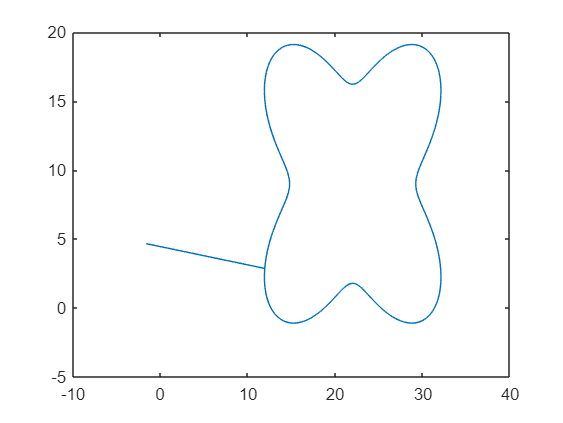



[xQ,yQ] = Cdirecta(l1,l2,q1S(:,2)*pi/180,q2S(:,2)*pi/180);
figure()
plot(xQ,yQ)

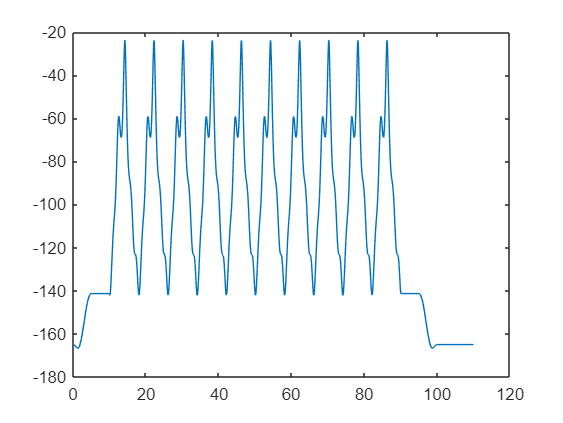



figure()
plot(q2S(:,1),q2S(:,2));

max(q2S(:,2))

ans = -23.8206

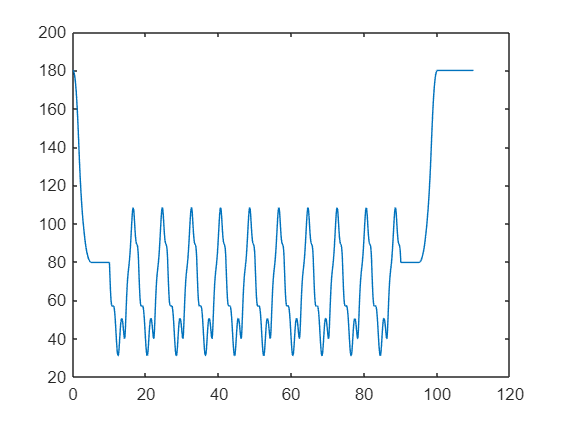


figure()
plot(q1S(:,1),q1S(:,2));

max(q2S(:,2))

ans = -23.8206